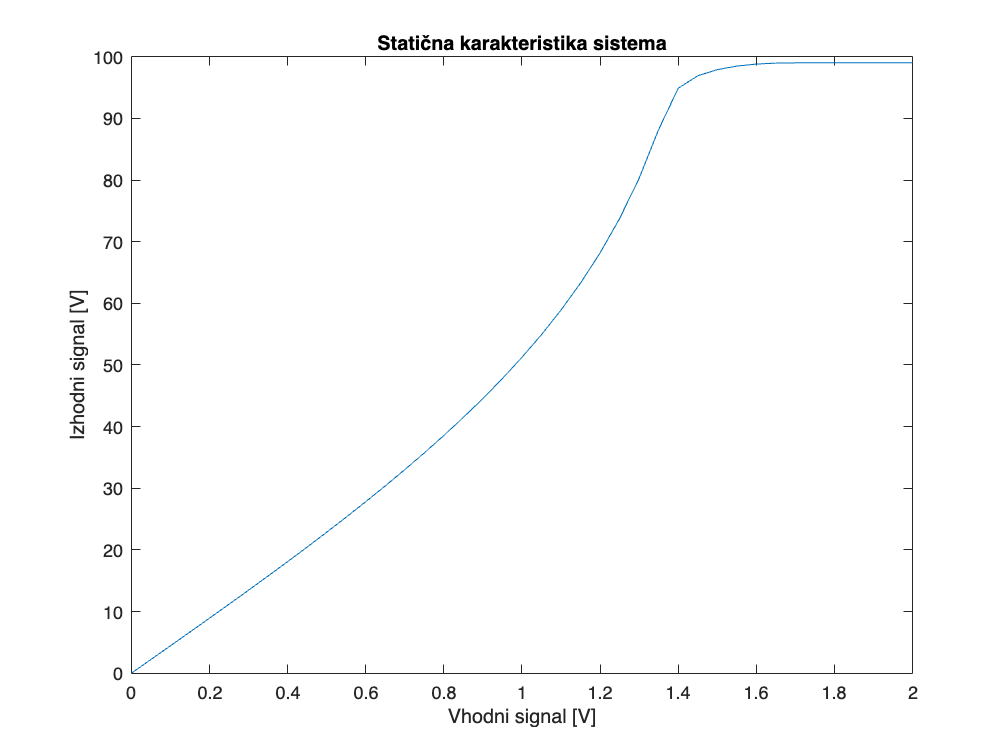

%Projekt 5

%Nastavitev parametrov
% Definicija parametrov
T = 0.01;
N = 300;
N_APRBS = 3000;
amplitude_train = 2.5;
amplitude_test = 2.0;
Th = 0.20;
padding = 100;
dV = 0.05;
c = zeros(2 / dV + 1, 1);

%Statična karaktersitika
% Inicializacija parametrov
numSteps = N;
stepSize = 0.05;
inputValues = 0:stepSize:2;  % Vrednosti vhodnega signala (0 do 2, korak 0.05)
outputValues = zeros(size(inputValues));  % Inicializacija vektorja za rezultate

% Glavna zanka za različne vrednosti vhodnega signala
for index = 1:length(inputValues)% skozi vse vhodne vrednosti
    currentInput = inputValues(index);  % Trenutna vrednost vhodnega signala
    u = currentInput * ones(numSteps, 1);  % Vhodni signal (vektor enakih vrednosti)

    % Inicializacija stanja sistema
    state = [0, 0];

    % Inicializacija izhodnega vektorja
    outputSignal = zeros(numSteps, 1);

    % Simulacija vzbujanja sistema
    for step = 1:numSteps
        % Klic funkcije sistema z vzbujanjem v vsakem trenutku
        [position, velocity] = helicrane(u(step), state);

        % Posodobitev stanja
        state = [velocity, position];

        % Shranjevanje trenutnega izhoda
        outputSignal(step) = position;
    end

    % Izračun povprečja izhodnih vrednosti po prehodnem obdobju
    steadyStateOutput = mean(outputSignal(100:end));

    % Shranjevanje rezultata v outputValues
    outputValues(index) = steadyStateOutput;
end

% Risanje rezultata
figure;
plot(inputValues, outputValues);
title("Statična karakteristika sistema");
xlabel("Vhodni signal [V]");
ylabel("Izhodni signal [V]");



%Generiranje in risanje APRBS signala
% Parametri
N = 1000; % Število vzorcev
Th = 2; % Časovna konstanta
T = 0.1; % Čas vzorčenja
amplitude_train = 2.5;
amplitude_test = 2.5;
padding = 100;
N_APRBS = N; % Število APRBS vzorcev

% Generiranje APRBS signala za treniranje
u_train = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);     % APRBS signal z N sampli med -1 in 1

idinput requires System Identification Toolbox.

d_train = diff(u_train);    % RArčuan razlike med zaporednimi elementi u_train
idx_train = find(d_train) + 1;  % +1 pozitivnim razlikam med zaporednimi vrednostim
idx_train = [1; idx_train];
for ii = 1:length(idx_train) - 1
    u_train(idx_train(ii):idx_train(ii + 1) - 1) = amplitude_train * rand;  % nastavi posamezne sample na random vrednost * amplitude_train
end
u_train(idx_train(end):end) = amplitude_train * rand;
u_train = [zeros(padding, 1); u_train];     % popadamo začetek traina z 0
u_train = u_train - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri testu more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Generiranje APRBS signala za testiranje, isti način kot za trening
u_test = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);
d_test = diff(u_test);
idx_test = find(d_test) + 1;
idx_test = [1; idx_test];
for ii = 1:length(idx_test) - 1
    u_test(idx_test(ii):idx_test(ii + 1) - 1) = amplitude_test * rand;
end
u_test(idx_test(end):end) = amplitude_test * rand;
u_test = [zeros(padding, 1); u_test];
u_test = u_test - 0.5; % Odštejemo 0.5, da premaknemo signal
% tukaj in pri train more it vzbujanje v negativ, drugače ga izhodni signal
% serje in pride gre proti 0

% Časovni vektorji
t_train = (0:length(u_train)-1) * T;
t_test = (0:length(u_test)-1) * T;

% Risanje rezultatov
figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Trening APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");



%odziv sistema na vhodni signal

% Simulacija odziva sistema za treniranje in testiranje
y_train = simulate_helicrane(u_train, [0 0]);
y_test = simulate_helicrane(u_test, [0 0]);

% Risanje rezultatov simulacije
figure
subplot(2, 1, 1);
plot(t_train, y_train);
title("Odziv procesa na trening vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

subplot(2, 1, 2);
plot(t_test, y_test);
title("Odziv procesa na testno vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

% Preverjanje dolžine vektorjev u_train in y_train
if length(u_train) > 2 && length(y_train) > 2
    % Priprava vhodnih in izhodnih podatkov za učenje v matrikah
    X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
    Y_train_podatki = y_train(3:end);

    % Premešanje podatkov za učenje
    perm_indeksi = randperm(size(X_train_podatki, 1));
    X_train_premesani = X_train_podatki(perm_indeksi, :);
    Y_train_premesani = Y_train_podatki(perm_indeksi, :);

    % Priprava vhodnih in izhodnih podatkov za testiranje
    X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
    Y_test_podatki = y_test(3:end);

    % Simulacija helicrana brez uporabe funkcije
    % Inicializacija stanja
    zacetno_stanje = [0, 0];

    % Dolžina vhoda
    N = length(u_train); % Tu mora biti dolžina u_train

    % Inicializacija izhoda
    izhodi = zeros(N, 1);

    % Glavna zanka za simulacijo
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u_train(i), zacetno_stanje);

        % Posodobitev stanja
        zacetno_stanje = [fip_, fi_];

        % Shranjevanje izhoda
        izhodi(i) = fi_;
    end

    % Prikaz končnih izhodov (izhodi)
    disp(izhodi);
else
    disp('Napaka: u_train ali y_train nimata dovolj elementov.');
end

%nevronska mreža

% Definicija arhitekture NN 
% 3 layerji, 15, 12, 10 nodov v layerjih
net = feedforwardnet([15, 12, 10]);
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'poslin';
net.trainParam.showWindow = false;      % Ne kaže trening zaslona
net.trainParam.goal = 2e-6;     % Mean squared error goal
[net, ~] = train(net, X_train_podatki', Y_train_podatki');  % Trening modela

% Napovedovanje na trening množici
Y_pred_train = net(X_train_podatki');

% Napovedovanje na testni množici
Y_pred_test = net(X_test_podatki');

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
title("Modeliranje trening množice z NN");
hold on;
plot(Y_pred_train);
xlabel("Vzorec");
ylabel("Odziv [V]");

subplot(2, 1, 2);
plot(Y_test_podatki);
title("Modeliranje testne množice z NN");
hold on;
plot(Y_pred_test);
xlabel("Vzorec");
ylabel("Odziv [V]");




%%Takagi sugento

%Takagi sugeno model

% 1) Priprava inputa in outputa
X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
Y_train_podatki = y_train(3:end);

% Normalizacija podatkov
mu_X_train = mean(X_train_podatki, 1);
sigma_X_train = std(X_train_podatki, 0, 1);
X_train_podatki = (X_train_podatki - mu_X_train) ./ sigma_X_train;

mu_Y_train = mean(Y_train_podatki, 1);
sigma_Y_train = std(Y_train_podatki, 0, 1);
Y_train_podatki = (Y_train_podatki - mu_Y_train) ./ sigma_Y_train;

% Dataset z normaliziranimi podatki
X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
X_test_podatki = (X_test_podatki - mu_X_train) ./ sigma_X_train;



% Parametri modela
R = 6; % Imamo približno 4 področja
alpha_initial = 0.001;  % learning rate
alpha_decay = 0.995;    % Decay rate
epochs = 300;

% Inicializacija parametrov
[C, U] = fcm(X_train_podatki, R); % kmeans za membership funckijo
O = ones(R, 1) * std(X_train_podatki);
W = rand(R, size(X_train_podatki, 2)) * 2 - 1; % Uteži
b = rand(R, 1) * 2 - 1; % Biasi


% Treniranje TS modela z validacijskimi preverjanji
for epoch = 1:epochs
    alpha = alpha_initial * (alpha_decay ^ epoch);
    e_avg = 0;
    for j = 1:size(X_train_podatki, 1)
        vhod = X_train_podatki(j, :)';
        cilj = Y_train_podatki(j);

        % Izračun aktivacijskih vrednosti (mu)
        % Broadcast vhod to match the dimensions of C and O
        vhod_broadcasted = repmat(vhod', size(C, 1), 1);
        ravniAktivacije = exp(-0.5 * sum((vhod_broadcasted - C).^2 ./ (O.^2), 2)); % aktivacijski vektor

        % Preprečevanje numerične nestabilnosti
        vsotaAktivacij = sum(ravniAktivacije);
        if vsotaAktivacij < 1e-6
            ravniAktivacije = ravniAktivacije + 1e-6;
            vsotaAktivacij = sum(ravniAktivacije);
        end

        ravniAktivacije = ravniAktivacije / vsotaAktivacij; % Normalizacija

        % Izračun utežene vsote in izhodne vrednosti
        utezenaVsota = W * vhod + b; % Utežena vsota
        izhod = sum(ravniAktivacije .* utezenaVsota); % Izhodna vrednost

        % Izračun gradientov za centre in širine
        razlikaCentrov = vhod_broadcasted - C;
        gradientCentrov = (razlikaCentrov ./ (O.^2)) .* ravniAktivacije;
        gradientSirin = (razlikaCentrov.^2 ./ (O.^3)) .* ravniAktivacije;

        % Verižno pravilo za gradientne izračune
        popravekUtezeneVsote = utezenaVsota - sum(utezenaVsota .* ravniAktivacije);
        gradientIzhodaCentrov = gradientCentrov .* popravekUtezeneVsote ./ (vsotaAktivacij.^2);
        gradientIzhodaSirin = gradientSirin .* popravekUtezeneVsote ./ (vsotaAktivacij.^2);

        % Gradienti za uteži in pristranskosti
        gradientPristranskosti = ravniAktivacije;
        gradientUtezi = ravniAktivacije * vhod';

        % Izračun napake
        napaka = (cilj - izhod).^2;

        % Posodobitev parametrov z uporabo učne hitrosti (ucnaHitrost)
        C = C + 2 * alpha * (cilj - izhod) * gradientIzhodaCentrov;
        O = O + 2 * alpha * (cilj - izhod) * gradientIzhodaSirin;
        b = b + 2 * alpha * (cilj - izhod) * gradientPristranskosti;
        W = W + 2 * alpha * (cilj - izhod) * gradientUtezi;

        e_avg = e_avg + napaka;
    end
    e_avg = e_avg / size(X_train_podatki, 1);

    if mod(epoch, 50) == 0
        fprintf("Epoka %d: Povprečna napaka: %f\n", epoch, e_avg);
    end
end


% Predikcija na obeh datasetih in rezultati
steviloVzorcev_train = size(X_train_podatki, 1);
Y_pred_train = zeros(1, steviloVzorcev_train);
for i = 1:steviloVzorcev_train
    vhod = X_train_podatki(i, :)';
    % Broadcast vhod to match the dimensions of C and O
    vhod_broadcasted = repmat(vhod', size(C, 1), 1);
    ravniAktivacije = exp(-0.5 * sum((vhod_broadcasted - C).^2 ./ (O.^2), 2));
    ravniAktivacije = ravniAktivacije / sum(ravniAktivacije);
    utezenaVsota = W * vhod + b;
    Y_pred_train(i) = sum(ravniAktivacije .* utezenaVsota);
end

steviloVzorcev_test = size(X_test_podatki, 1);
Y_pred_test = zeros(1, steviloVzorcev_test);
for i = 1:steviloVzorcev_test
    vhod = X_test_podatki(i, :)';
    % Broadcast vhod to match the dimensions of C and O
    vhod_broadcasted = repmat(vhod', size(C, 1), 1);
    ravniAktivacije = exp(-0.5 * sum((vhod_broadcasted - C).^2 ./ (O.^2), 2));
    ravniAktivacije = ravniAktivacije / sum(ravniAktivacije);
    utezenaVsota = W * vhod + b;
    Y_pred_test(i) = sum(ravniAktivacije .* utezenaVsota);
end

% Denormalizacija
Y_pred_train = (Y_pred_train * sigma_Y_train) + mu_Y_train;
Y_pred_test = (Y_pred_test * sigma_Y_train) + mu_Y_train;

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(y_train, 'b', 'DisplayName', 'Dejanski odziv');
hold on;
plot(Y_pred_train, 'r', 'DisplayName', 'Napovedani odziv');
title('Dejanski vs. napovedani odziv (trening)');
xlabel('Vzorec');
ylabel('Odziv [V]');
legend('show');

subplot(2, 1, 2);
plot(y_test, 'b', 'DisplayName', 'Dejanski odziv');
hold on;
plot(Y_pred_test, 'r', 'DisplayName', 'Napovedani odziv');
title('Dejanski vs. napovedani odziv (test)');
xlabel('Vzorec');
ylabel('Odziv [V]');
legend('show');
ylim([0 120]);

% Shranjevanje mehkega modela
save('ts_model.mat', 'C', 'O', 'W', 'b');
